# DidToolbox: Real Data Example

Dr. Ralf Elsas-Nicolle, LMU Munich, Germany

Last change: 11/16/2025

## 0    Overview

This example illustrates using the Matlab DiD Toolbox in a real world application - a test of the so-called "Castle Doctrine" (a change in U.S. self-defense law) on the homicides before and after the change in law. This analysis is based on the example in Scott Cunningham's diff-in-diff blog and the study by *Cheng & Hoekstra (2013)*.

*Background*

From 2000 to 2010, more than 20 states passed the so-called “Castle Doctrine” law. For example, in 2005, the US state of Florida introduced a variant law dubbed “Stand Your Ground”. This expanded the existing “castle” doctrine – a legal doctrine in the US concerning lethal self-defense within one’s home. Whereas in other cases a victim has the duty to retreat from danger, within their own home, castle doctrine allows the application of lethal self-defense under some conditions. “Stand Your Ground” in Florida expanded the applicability of castle doctrine to include public spaces, a controversial change, especially due to concerns about an increase in violence. Other federal states followed, with all law changes occurring in the period from 2005-2009.

As “Stand Your Ground” laws, such as the one in Florida, state that use of violent force is permissible if the user “reasonably believes” it is necessary to avert death, injury, or another violent crime, many feared that this would result in a lowered barrier to using lethal force and possibly vigilantism.

For this reason, the issue came under scrutiny from various sources, one of these being a paper by Cheng & Hoekstra, published in 2013. They investigate whether “Stand Your Ground” laws resulted in an increase in homicides, as feared by many of their critics. It is important to note that the key variable of interest “homicide” (measured in logs per 100,000 inhabitants) does not (!) capture self-defense killings but only murder and non-negligent manslaughter, so killings that even under the castle doctrine are illegal. Cheng’s & Hoekstra’s data set included details on crime rates, socioeconomic factors, and particularly homicide rates in all US states between the years of 2000 and 2010, using the introduction of “Stand Your Ground” laws as a treatment.

Also, estimator settings are such that they resemble the default settings in Stata 18, so that direct comparisons (using the same data) are possible. A Stata log-file with results for the Castle Doctrine data is available here. 

## 1    Load data and look at descriptive statistics

In the first step we load the relevant data.


clear; close all;
tbl = readtable(".\Data\castleData.xlsx");

tbl = sortrows(tbl,["sid","year"]); 


First descriptive statistic is the list of federal states and their respective treatment year:

firstTreatYear = varfun(@min, tbl(tbl.treatPost==1,:), ...
    'InputVariables','year', 'GroupingVariables','state');
firstTreatYear.Properties.VariableNames{'min_year'} = 'firstYear'

firstTreatYear = 21×3 table
         state          GroupCount    firstYear
    ________________    __________    _________

    {'Alabama'     }        4           2007   
    {'Alaska'      }        4           2007   
    {'Arizona'     }        4           2007   
    {'Florida'     }        5           2006   
    {'Georgia'     }        4           2007   
    {'Indiana'     }        4           2007   
    {'Kansas'      }        4           2007   
    {'Kentucky'    }        4           2007   
    {'Louisiana'   }        4           2007   
    {'Michigan'    }        4           2007   
    {'Mississippi' }        4           2007   
    {'Missouri'    }        3           2008   
    {'Montana'     }        1           2010   
    {'North Dakota'}        3           2008   
    {'Ohio'        }        2           2009   
    {'Oklahoma'    }        4           2007   


Second, we use the toolbox to better understand the data. Recall that in practice, treatment of units doesn't have to be absorptive but could be "on/off". Therefore, the data description also provides information on whether there are units/cohorts in the data, where treatment is turned off after some time ("Leavers"). This is not the case in the Castle Doctrine data. 

% Instantiate data
ds = did.Dataset.fromTable(tbl, idVar="sid", timeVar="year",yVar="l_homicide", dVar="treatPost",describe=true);  


[DataDesc] Units = 50 | Periods = 11 | Nobs = 550 | Balanced Units = 50 (100.0%)
[DataDesc] Ever-treated = 21 (42.0%) | Never-treated = 29 (58.0%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

       "2006"          1       0.02         0                   0                    2006      
       "2007"         13       0.26         0                   0                    2007      
       "2008"          4       0.08         0                   0                    2008      
       "2009"          2       0.04         0                   0                    2009      
       "2010"     


%% Descriptive Statistics (automatically with data initialisation) 
% descript = did.dataDesc(tbl, idVar="sid", timeVar="year",yVar="l_homicide", dVar="treatPost");

## 2    Standard TWFE and Bacon decomposition

To try understand the impact of the Castle Doctrine, we first run a standard two-way fixed effects (TWFE) estimation. This ignores the staggered introduction of the law in different states over time. 

tic
resTWFE = did.fit("twfe", ds,  vcov="clustered", ...
    clusters=["gvar"],absorbUseGPU=false,details=true);

  [absorbAPM] iter    1: relChange = 2.057e+00
  [absorbAPM] CONVERGED at iter 2 (relChange 4.084e-16 < tol 1.0e-08)
[TWFE] ATT(treatPost) = 0.069398
[TWFE] Standard errors clustered by gvar 
[TWFE]
  1×5 table

       Name        Estimate       SE       tStat      pValue 
    ___________    ________    ________    ______    ________

    "treatPost"    0.069398    0.017528    3.9594    0.010749



toc

Elapsed time is 0.050634 seconds.


The result is an average average effect on the treated (ATT) of 0.069, i.e. homicide rates go up on average by about 7%.

But as we know about the staggered introduction, we conduct the Bacon decomposition, which basically shows how the different comparisons between treated and non-treated states enter the TWFE ATT estimate. 

resBacon = did.fit("bacon", ds);


---- Bacon: Overall (TWFE) -----
    0.0694

Bacon: ---- Comparisons -----
               type               group1    group2      weight      estimate 
    __________________________    ______    ______    __________    _________

    "Treated vs Never Treated"     2006         0       0.050306      0.14503
    "Treated vs Never Treated"     2007         0        0.61039     0.059254
    "Treated vs Never Treated"     2008         0        0.16098      0.09201
    "Treated vs Never Treated"     2009         0       0.060368      0.18195
    "Treated vs Never Treated"     2010         0       0.016769      0.07399
    "Treated earlier vs later"     2006      2007      0.0045102     0.042003
    "Treated earlier vs later"     2006      2008      0.0027755      0.09126
    "Treated earlier vs later"     2006      2009  

The Bacon decomposition shows all pairwise comparisons over different time period combination, for each of the five cohorts whose treatment started in 2006, 2007, 2008, 2009 and 2010, respectively. It shows the cohort-year specific coefficient contribution as well as its weight, i.e. how much the estimate contributes to the overall TWFE ATT estimate. 

Already the pairwise comparison table shows that TWFE implicitly contains "forbidden" comparisons - in particular "Treated later vs earlier" and therefore potentially introduces bias into the ATT estimate if treatment effects differ between cohorts.  The table showing aggregated coefficient by group of comparisons and the respective weights illustrates heterogeneity in cohort effects. However, the weight of potentially troublesome comparisons is relatively low (about 10%) which implies that any bias may not be too severe. This impact depends on the specific setting being analyzed. 

Goodman-Bacon shows in his analysis though that weights of bad comparisons can be even negative and absolutely large (depending on cohort sizes and differences in cohort ATTs).   

## 3    Staggered DiD estimation 

### 3.1    Overview

In the next step, we analyze different estimators that are specifically designed to deal with staggered DiD settings. As DiD analyses always aim to estimate a counterfactual component (i.e. what would have been the outcome for a treated unit if it would not have been treated), assumptions on how to use the control groups pre-treatment characteristics to estimate the counterfactual are necessary (the famous "parallel trends" assumption). 

The estimators mostly differ in implicit assumption about anticipation of treatment effects and and characteristics of the used control group. Except for one, all estimators also assume that the treatment is absorptive, i.e. it is switched on but never (in the data) goes away. Only the *de Chaisemartin/d'Haultfoeuille (2020)* estimator (CH in the toolbox) can take "on/off"-type of treatments into account. It also differs from the other estimators in measuring treatment effects only in the very first period treatment for each cohort.    

### 3.2    Wooldridge and BJS

Two estimators basically just use an extended OLS framework - *Wooldridge (2021)* (*Wooldridge* in the toolbox) and *Borusyak et al. (2024)*. The Wooldridge estimator specifies one particular regression equation while Borusyak (*BJS* in the toolbox) first runs a regression using only untreated observations and from that estimates treatment effects in a second step.  

resWool = did.fit("wooldridge", ds, ...
    vcov="clustered", clusters="gvar", details=false);

[wooldridge] ATT by cohort (mean of cohorts coefficients):
    Cohort    #TimePeriods     ATT(k)         SE          tStat         pValue  
    ______    ____________    ________    __________    __________    __________

       7           5           0.12768    0.00028364        450.15     0.0014142
       8           4          0.048677     0.0029157        16.695      0.038088
       9           3          0.083532    1.2034e-18    6.9413e+16    9.1715e-18
      10           2           0.17615    2.7563e-18     6.391e+16    9.9613e-18
      11           1           0.07399    2.6594e-18    2.7822e+16    2.2882e-17

[wooldridge] Overall ATT (cohort-share weighted):
    Estimate       SE        tStat      pValue 
  

In comparison, we could also have used the BJS estimator, that conducts ATT estimation in two steps. 

resBJS = did.fit("BJS", ds);


[BJS] Untreated-only fit on ALL D==0: N_untreated = 476 | Units = 50 | Periods = 11
[BJS] Treated identified: 74/74 (100.0%)
[BJS] Overall ATT = 0.0669 (SE=0.0593; 95% CI [-0.0493, 0.1831])
ATT by Cohort
    cohort    ATT_obs      SD_obs     N_obs     SE_obs     CI_lo_obs    CI_hi_obs
    ______    ________    ________    _____    ________    _________    _________

       7       0.12768    0.033517      5      0.014989     0.086066      0.1693 
       8      0.048677     0.26921     52      0.037333    -0.026272     0.12363 
       9      0.083532     0.25941     12      0.074886    -0.081291     0.24835 
      10       0.17615     0.15191      4      0.075955     -0.06557     0.41787 
      11       0.07399           0      1             0      0.0

### 3,3    de Chaisemartin / d'Haultfoeuille (CH)

The CH estimator only measures treatment effects at the first period of treatment per cohort. Also it allows for on/off-treatments. Here we do not illustrate the latter issue but show estimates for the Castle Doctrine data (which has no leavers). Accordingly, in the output the "Leavers-only" row (summary table)  and the DID_minus column (cohort aggregation) are empty. The overall effect is 0.01, which is statistically insignificant. 

CH also reports a placebo test, where two untreated periods of the cohorts are compared (if available in the data). It basically asks "*Before treatment starts, do the groups that will be treated later already evolve differently from the control groups?*” This placebo test actually raises concerns about the Castle Doctrine data as it fails to be insignificant, thereby showing a potential violation of the parallel trends assumption. 

resCH = did.fit("DID_M", ds);


=== DID_M summary (table) ===
              Effect               Estimate       SE          t          p    
    ___________________________    ________    ________    _______    ________

    "DID_M"                        0.010336    0.078704    0.13132     0.89606
    "Joiners-only"                 0.010336    0.078704    0.13132     0.89606
    "Leavers-only"                        0           0        NaN         NaN
    "Overall (cohort-weighted)"    0.010336    0.068596    0.15067     0.88085
    "Placebo DID_M"                 0.10258    0.045302     2.2643    0.028017


=== DID_M by Cohort (table) ===
     t      DID_plus    DID_minus
    ____    ________    _________

    2006     0.19373       NaN   
    20

### 3.4    Callaway / Sant'Anna (CS)

The CS estimator deals with cohorts and times separately by analyzing ATT(g,t) and then aggregating the results in flexible ways. It is particularly suited to handle covariates, as it uses (up to) two versions of modeling their influence on treated und untreated individuals. 

- *Outcome Regression (RA/OR)*: estimates the untreated counterfactual outcome evolution conditional on covariates. This can work even with weak overlap, because it extrapolates the outcome model to treated units whose covariate profiles are not observed in the control group.

- *Inverse Probability Weighting (IPW)*: reweights untreated units so their covariate distribution matches that of the treated group. This directly addresses compositional bias from covariate imbalance.

- *Doubly Robust (DR)*: combines OR and IPW so that the ATT estimate is consistent if either the outcome model or the propensity score model is correctly specified. This provides “extra protection” against model misspecification, and even when both models are slightly wrong, DR typically performs better asymptotically than either method alone.

We use either of the two methods to calculate standard errors ("multiplier" and "clustered"). Clustering is over cohorts and the control group is chosen to be both never as well as not-yet treated units. Note that if one chose the control as being "never" the standard errors become (weirdly) extremely tiny, probably due to the small sample and group sizes (the same effect shows in the Stata analysis).

resCS = did.fit("cs", ds, ...
               Comparison="notyet", Delta=0, Approach="unconditional", ClusterVar="gvar",...
               SEMethod="clustered",Weighting="treatedObs");  

[CS] R=15 cells; Approach=unconditional; Comp=notyet; δ=0; SE=clustered; W=treatedObs. 
[CS] Overall ATT 
  1×7 table

    Estimate       SE        tStat       pValue         LB           UB       crit
    ________    _________    ______    __________    _________    ________    ____

    0.017412    0.0041567    4.1889    2.8035e-05    0.0092648    0.025559    1.96

[CS] Estimates 
  15×11 table

          Name             Effect      Estimate     g     t         SE           tStat         pValue

resCS = did.fit("cs", ds, ...
    Comparison="notyet", Delta=0, Approach="unconditional", ...
    SEMethod="multiplier", ...
    B=999, Seed=42, multiplier="mammen");

[CS] R=15 cells; Approach=unconditional; Comp=notyet; δ=0; SE=multiplier; W=treatedObs. Bootstrap B=999, crit(95%)=2.703
[CS] Overall ATT 
  1×6 table

    Estimate       SE       tStat    pValue        LB           UB   
    ________    ________    _____    _______    _________    ________

    0.017412    0.035535    0.49     0.62062    -0.053353    0.088177

[CS] Estimates 
  15×11 table

          Name             Effect      Estimate     g     t        SE        tStat       pValue     gYear    t

## 4 Conclusions

This example served to illustrate the DiD Toolbox for Matlab in a real world analysis setting, looking at the impact of the Castle Doctrine on homicides in the U.S. 

In terms of economic results, the original paper documents an increase in homicides between 5% - 8%, depending on their model specification. When using the nowadays available modern estimators for staggered DiD analyses, the evidence becomes less strong. To illustrate, the following graphs compare the estimated cohort effects for *Callaway/Sant'Anna* (CS) and *Borusyak et al.* (BJS) showing that only for two cohorts (2006 and 2010) effects appear to be statistically significant (with a lot of heterogeneity across cohorts in term of point estimates). Both cohorts, however, comprise only two federal states, Florida and Montana, respectively. 

Also, the *de Chaisemartin/d'Haultfoeuille* (CH) estimator indicates potential violations of the parallel trend assumption, as no coefficient for ATT is significant but the placebo test (comparing untreated periods of cohorts) has a significant finding, thus raising doubts on parallel trends. 

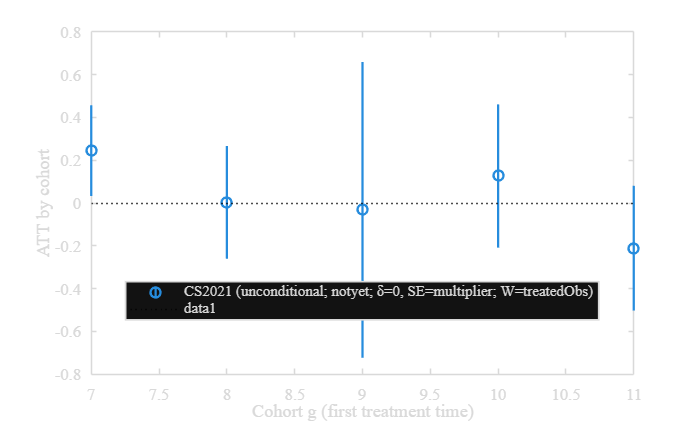

did.did_plot(resCS, "cohort");      

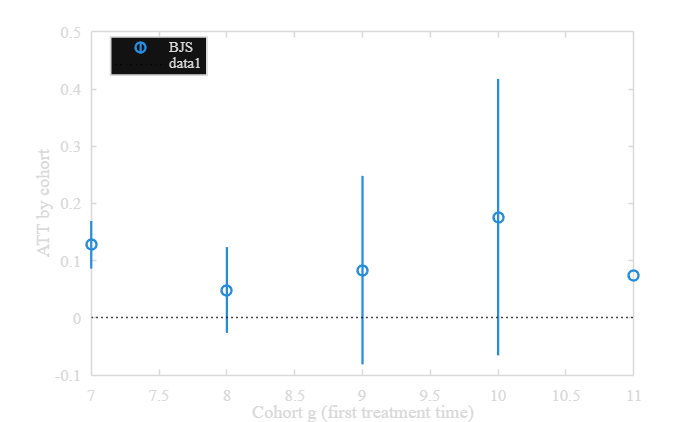

did.did_plot(resBJS,"cohort");

## Literature

Borusyak, K. / Jaravel, X. / Spiess, J. (2024). Revisiting Event-Study Designs: Robust and Efficient Estimation, Review of Economic Studies, 00, 1–33.

Cheng C. / Hoekstra, M.  (2013): Does Strengthening Self-Defense Law Deter Crime or Escalate Violence? Evidence from Expansions to Castle Doctrine,The Journal of Human Resources, Vol. 48, No. 3, pp. 821-853.

Callaway, B. / Sant’Anna, P. (2021): Difference-in-Differences with Multiple Time Periods, *Journal of Econometrics* 225 (2): 200–230.

de Chaisemartin, C. / D'Haultfœuille, X. (2020): Two-Way Fixed Effects Estimators with Heterogeneous Treatment Effects, American Economic Review, 110(9), 2964–2996.

Sant’Anna, P. / Zhao, J. (2020): Doubly Robust Difference-in-Differences Estimators, *Journal of Econometrics* 219 (1): 101–122.

Wooldridge, J. (2021). Two-Way Fixed Effects, the Two-Way Mundlak Regression, and Event Study Estimators. Working Paper.